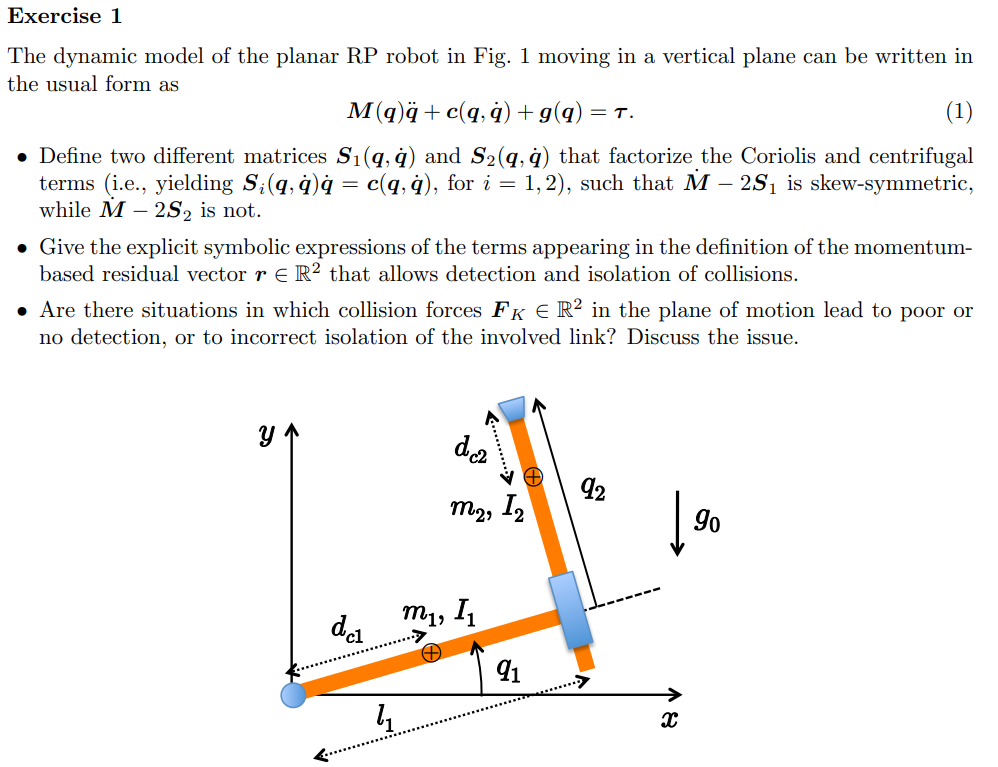

syms q1 q2 q_dot_1 q_dot_2 m_1 m_2 d_1 d_2 L_2 L_1 I_1 I_2 g0 real

x1 = d_1*cos(q1);
y1 = d_1*sin(q1);
vx1 = diff(x1,q1)*q_dot_1+diff(x1,q2)*q_dot_2

$$vx1 = -d_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)$$

vy1 = diff(y1,q1)*q_dot_1+diff(y1,q2)*q_dot_2

$$vy1 = d_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)$$

T1 = simplify(0.5*m_1*[vx1 vy1]*[vx1; vy1;]+0.5*I_1*[0 0 q_dot_1]*[0; 0; q_dot_1;])

$$T1 = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{d_{1}}^{2}+I_{1}\right)}{2}$$


x2 = L_1*cos(q1)-(q2-d_2)*sin(q1);
y2 = L_1*sin(q1)+(q2-d_2)*cos(q1);
vx2 = diff(x2,q1)*q_dot_1+diff(x2,q2)*q_dot_2

$$vx2 = -{\dot{q}}_{1}\,\left(L_{1}\,\sin\left(q_{1}\right)-\cos\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\right)-{\dot{q}}_{2}\,\sin\left(q_{1}\right)$$

vy2 = diff(y2,q1)*q_dot_1+diff(y2,q2)*q_dot_2

$$vy2 = {\dot{q}}_{1}\,\left(L_{1}\,\cos\left(q_{1}\right)+\sin\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\right)+{\dot{q}}_{2}\,\cos\left(q_{1}\right)$$

T2 = simplify(0.5*m_2*[vx2 vy2]*[vx2; vy2;]+0.5*I_2*[0 0 q_dot_1]*[0; 0; q_dot_1;])

$$T2 = \frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,{\left({\dot{q}}_{1}\,\left(L_{1}\,\cos\left(q_{1}\right)+\sin\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\right)+{\dot{q}}_{2}\,\cos\left(q_{1}\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left({\dot{q}}_{1}\,\left(L_{1}\,\sin\left(q_{1}\right)-\cos\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\right)+{\dot{q}}_{2}\,\sin\left(q_{1}\right)\right)}^{2}}{2}$$

T = T1+T2

$$T = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{d_{1}}^{2}+I_{1}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,{\left({\dot{q}}_{1}\,\left(L_{1}\,\cos\left(q_{1}\right)+\sin\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\right)+{\dot{q}}_{2}\,\cos\left(q_{1}\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left({\dot{q}}_{1}\,\left(L_{1}\,\sin\left(q_{1}\right)-\cos\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\right)+{\dot{q}}_{2}\,\sin\left(q_{1}\right)\right)}^{2}}{2}$$


% Inertia Matrix
M11 = diff(diff(T, q_dot_1), q_dot_1);
M12 = diff(diff(T, q_dot_1), q_dot_2);

M21 = diff(diff(T, q_dot_2), q_dot_1);
M22 = diff(diff(T, q_dot_2), q_dot_2);

M = simplify([M11, M12; M21, M22;])

$$M = \left(\begin{array}{cc} I_{1}+I_{2}+{d_{1}}^{2}\,m_{1}+m_{2}\,{\left(L_{1}\,\cos\left(q_{1}\right)+\sin\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\right)}^{2}+m_{2}\,{\left(L_{1}\,\sin\left(q_{1}\right)-\cos\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\right)}^{2} & L_{1}\,m_{2}\\ L_{1}\,m_{2} & m_{2} \end{array}\right)$$


% Coriolis and Centrifugal terms
q  = [q1; q2;];
dq = [q_dot_1; q_dot_2;];
C = sym(zeros(2,2));

for i = 1:2
    for j = 1:2
        tmp = 0;
        for k = 1:2
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp)  % semplifico
    end
end

$$C = \left(\begin{array}{cc} -m_{2}\,{\dot{q}}_{2}\,\left(d_{2}-q_{2}\right) & 0\\ 0 & 0 \end{array}\right)$$

$$C = \left(\begin{array}{cc} -m_{2}\,{\dot{q}}_{2}\,\left(d_{2}-q_{2}\right) & -m_{2}\,{\dot{q}}_{1}\,\left(d_{2}-q_{2}\right)\\ 0 & 0 \end{array}\right)$$

$$C = \left(\begin{array}{cc} -m_{2}\,{\dot{q}}_{2}\,\left(d_{2}-q_{2}\right) & -m_{2}\,{\dot{q}}_{1}\,\left(d_{2}-q_{2}\right)\\ m_{2}\,{\dot{q}}_{1}\,\left(d_{2}-q_{2}\right) & 0 \end{array}\right)$$

$$C = \left(\begin{array}{cc} -m_{2}\,{\dot{q}}_{2}\,\left(d_{2}-q_{2}\right) & -m_{2}\,{\dot{q}}_{1}\,\left(d_{2}-q_{2}\right)\\ m_{2}\,{\dot{q}}_{1}\,\left(d_{2}-q_{2}\right) & 0 \end{array}\right)$$


c_vec = simplify(C * dq);

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cc} -m_{2}\,{\dot{q}}_{2}\,\left(d_{2}-q_{2}\right) & -m_{2}\,{\dot{q}}_{1}\,\left(d_{2}-q_{2}\right)\\ m_{2}\,{\dot{q}}_{1}\,\left(d_{2}-q_{2}\right) & 0 \end{array}\right)$$

disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} -2\,m_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\left(d_{2}-q_{2}\right)\\ m_{2}\,{{\dot{q}}_{1}}^{2}\,\left(d_{2}-q_{2}\right) \end{array}\right)$$


% Gravity terms
U1 = m_1*g0*(y1)

$$U1 = d_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)$$

U2 = m_2*g0*(y2)

$$U2 = g_{0}\,m_{2}\,\left(L_{1}\,\sin\left(q_{1}\right)-\cos\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\right)$$

U = [U1+U2]

$$U = g_{0}\,m_{2}\,\left(L_{1}\,\sin\left(q_{1}\right)-\cos\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\right)+d_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)$$

g_q = simplify([diff(U,q1); diff(U,q2);])

$$g\_q = \left(\begin{array}{c} g_{0}\,m_{2}\,\left(L_{1}\,\cos\left(q_{1}\right)+\sin\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\right)+d_{1}\,g_{0}\,m_{1}\,\cos\left(q_{1}\right)\\ g_{0}\,m_{2}\,\cos\left(q_{1}\right) \end{array}\right)$$


% Derivative of Inertia Matrix
m_dot_11 = diff(M(1,1),q1)*q_dot_1+diff(M(1,1),q2)*q_dot_2

$$m\_dot\_11 = {\dot{q}}_{2}\,\left(2\,m_{2}\,\cos\left(q_{1}\right)\,\left(L_{1}\,\sin\left(q_{1}\right)-\cos\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\right)-2\,m_{2}\,\sin\left(q_{1}\right)\,\left(L_{1}\,\cos\left(q_{1}\right)+\sin\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\right)\right)$$

m_dot_12 = diff(M(1,2),q1)*q_dot_1+diff(M(1,2),q2)*q_dot_2

$$m\_dot\_12 = 0$$

m_dot_21 = diff(M(2,1),q1)*q_dot_1+diff(M(2,1),q2)*q_dot_2

$$m\_dot\_21 = 0$$

m_dot_22 = diff(M(2,2),q1)*q_dot_1+diff(M(2,2),q2)*q_dot_2

$$m\_dot\_22 = 0$$


M_dot = simplify([m_dot_11 m_dot_12; m_dot_21 m_dot_22;])

$$M\_dot = \left(\begin{array}{cc} -2\,m_{2}\,{\dot{q}}_{2}\,\left(d_{2}-q_{2}\right) & 0\\ 0 & 0 \end{array}\right)$$


% --- Input vector ---
% Tempo simbolico
syms t real

% Definizione di q1(t), q2(t)
syms q1(t) q2(t)

% Derivate rispetto al tempo
q_dot_1_t = diff(q1, t);
q_dot_2_t = diff(q2, t);

% Versioni scalari simboliche per costruire M
syms q1s q2s q_dot_1s q_dot_2s

% Risostituzione della M simbolica in funzione di q1(t), q2(t)
M_t = subs(M, {q1s, q2s}, {q1(t), q2(t)});

% Vettore delle derivate
dq_t = [q_dot_1_t; q_dot_2_t];

% Calcolo momento generalizzato p(t)
p_t = simplify(M_t * dq_t);

% Termini alpha simbolici generici
syms alpha1 alpha2 real
alpha = [alpha1; alpha2];

% Torques simbolici
syms tau_1 tau_2 real
tau = [tau_1; tau_2];

% Guadagno del filtro
syms K1 K2 real
K = diag([K1, K2]);

% Residual con formulazione integrale
int_term = int(tau - alpha, t);
r_t = simplify(K * (int_term - p_t));

disp('Residual vector r(t) with integral formulation is:');

Residual vector r(t) with integral formulation is:


disp(r_t);

$$\left(\begin{array}{c} -K_{1}\,\left(\left(I_{1}+I_{2}+{d_{1}}^{2}\,m_{1}+m_{2}\,{\left(L_{1}\,\cos\left(q_{1}\right)+\sin\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\right)}^{2}+m_{2}\,{\left(L_{1}\,\sin\left(q_{1}\right)-\cos\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\right)}^{2}\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+t\,\left(\alpha_{1}-\tau_{1}\right)+L_{1}\,m_{2}\,\frac{\partial }{\partial t}q_{2}\left(t\right)\right)\\ -K_{2}\,\left(t\,\left(\alpha_{2}-\tau_{2}\right)+m_{2}\,\frac{\partial }{\partial t}q_{2}\left(t\right)+L_{1}\,m_{2}\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right) \end{array}\right)$$

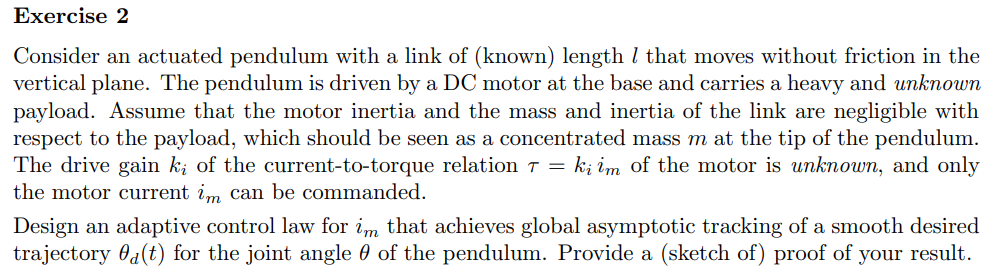

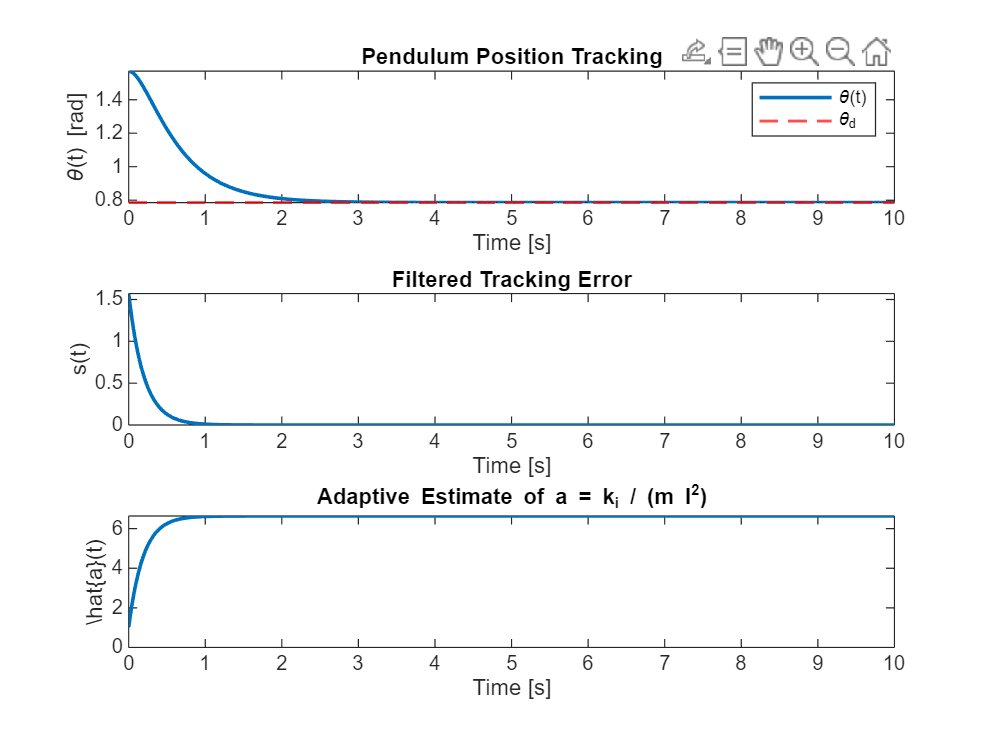

% Parametri fisici
g = 9.81;    % Gravità [m/s^2]
l = 1.0;     % Lunghezza del pendolo [m]

% Parametri del controllore
lambda = 2.0;
k = 5.0;
gamma = 10.0;

% Traiettoria desiderata (costante)
theta_d = @(t) pi/4;
dtheta_d = @(t) 0;
ddtheta_d = @(t) 0;

% Equazioni differenziali
dynamics = @(t, y) [
    y(2);  % dtheta
    -g/l * sin(y(1)) + y(3) * (1 / y(3)) * ...
    (ddtheta_d(t) - lambda * (y(2) - dtheta_d(t)) + g/l * sin(y(1)) - k * (y(2) - dtheta_d(t) + lambda * (y(1) - theta_d(t))));
    gamma * (y(2) - dtheta_d(t) + lambda * (y(1) - theta_d(t))) * ...
    (1 / y(3)) * (ddtheta_d(t) - lambda * (y(2) - dtheta_d(t)) + g/l * sin(y(1)) - k * (y(2) - dtheta_d(t) + lambda * (y(1) - theta_d(t))))
];

% Condizioni iniziali: [theta; dtheta; a_hat]
theta0 = pi/2;
dtheta0 = 0;
a_hat0 = 1.0;
y0 = [theta0; dtheta0; a_hat0];

% Simulazione
tspan = [0 10];
[t, Y] = ode45(dynamics, tspan, y0);

theta = Y(:,1);
dtheta = Y(:,2);
a_hat = Y(:,3);

% Calcolo s(t)
s = dtheta - dtheta_d(t) + lambda * (theta - theta_d(t));
% Plot
figure;

subplot(3,1,1);
plot(t, theta, 'LineWidth', 1.5); hold on;
yline(theta_d(0), 'r--', 'LineWidth', 1.2);
xlabel('Time [s]');
ylabel('\theta(t) [rad]');
title('Pendulum Position Tracking');
legend('\theta(t)', '\theta_d');

subplot(3,1,2);
plot(t, s, 'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('s(t)');
title('Filtered Tracking Error');

subplot(3,1,3);
plot(t, a_hat, 'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('\hat{a}(t)');
title('Adaptive Estimate of a = k_i / (m l^2)');